clc;
clear;
close all;

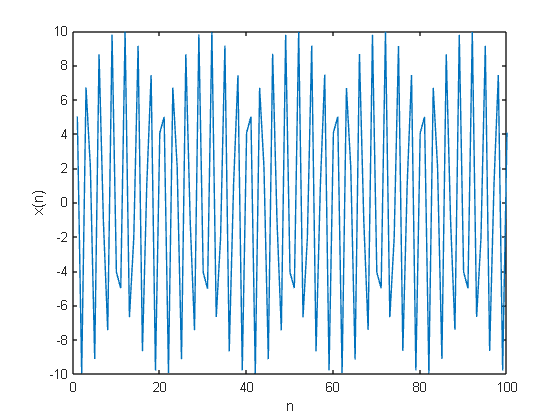

% Data Generation
N = 100;
n = (0:N-1)';
A_original = 10;
f0_true = 0.35;
phi = pi/3;
sig = 0.01;
tol = 1e-6;
w = randn(N,1)*sig;
x = A_original*cos(2*pi*f0_true.*n+phi) + w;
plot(x);
xlabel('n');
ylabel('x(n)');

% Signal to Noise Ratio
% Compute the power of the signal
power_signal = sum(x.^2) / N;

% Compute the power of the noise
power_noise = sum(w.^2) / N;

SNR = power_signal/power_noise;
fprintf('SNR: %.3f\n', SNR);

SNR: 562992.252



% Calculate SNR in dB
SNR_dB = 10 * log10(power_signal / power_noise);

% Display SNR

fprintf('SNR(dB): %.3f dB\n', SNR_dB);

SNR(dB): 57.505 dB


% Newton-Raphson Method for estimation of A
A_init=1;
A_est=newton_raphson_A(n,sig,A_init,x,tol,f0_true,phi);

% Finding the 95% confidence interval of the estimated A
alpha = 0.05;
df = N - 1;
t = tinv(1-alpha/2, df);
se = sqrt(sum((x - A_est.*cos(2*pi*f0_true.*n+phi)).^2)/(N-1));
ci = [A_est-t*se, A_est+t*se];

% Displaying the results
fprintf('True value of A: %.4f\n', A_original);

True value of A: 10.0000


fprintf('Estimated value of A: %.4f\n', A_est);

Estimated value of A: 10.0018


fprintf('95%% confidence interval of A: [%.4f, %.4f]\n\n', ci);

95% confidence interval of A: [9.9831, 10.0204]



% Newton-Raphson Method for estimation of ∅
phi_init=pi/4;
phi_est=newton_raphson_phi(n,sig,phi_init,x,tol,f0_true,A_original);

% Finding the 95% confidence interval of the estimated ∅
alpha = 0.05;
df = N - 1;
t = tinv(1-alpha/2, df);
se = sqrt(sum((x - A_original*cos(2*pi*f0_true.*n+phi_est)).^2)/(N-1));
ci = [phi_est-t*se, phi_est+t*se];

% Displaying the results
fprintf('True value of ∅: %.4f\n', phi);

True value of ∅: 1.0472


fprintf('Estimated value of ∅: %.4f\n', phi_est);

Estimated value of ∅: 1.0471


fprintf('95%% confidence interval of ∅: [%.4f, %.4f]\n\n', ci);

95% confidence interval of ∅: [1.0284, 1.0659]



% Estimating f0
f_est=Estimate_f0(x,n,N);

disp(['True value of f0: ', num2str(f0_true)]);

True value of f0: 0.35


disp(['Estimated value of f0: ', num2str(f_est)]);

Estimated value of f0: 0.35035


% Non-Linear Least Squares Estimation
% Initial guesses for the parameters
A_guess = 1;
f0_guess = 0.15;
phi_guess = pi/4;
initial_guess = [A_guess, f0_guess, phi_guess];

% Define the objective function
objective_function = @(params) params(1)*cos(2*pi*params(2)*n + params(3)) - x;

% Perform nonlinear least squares estimation
options = optimoptions('lsqnonlin', 'Display', 'off');
estimated_params = lsqnonlin(objective_function, initial_guess, [], [], options);

% Extract the estimated parameters
A_estimated = estimated_params(1);
f0_estimated = estimated_params(2);
phi_estimated = estimated_params(3);

% Display the estimated parameters
disp(['Estimated A: ', num2str(A_estimated)]);

Estimated A: 0.01808


disp(['Estimated f0: ', num2str(f0_estimated)]);

Estimated f0: 0.074501


disp(['Estimated phi: ', num2str(phi_estimated)]);

Estimated phi: 1.5895


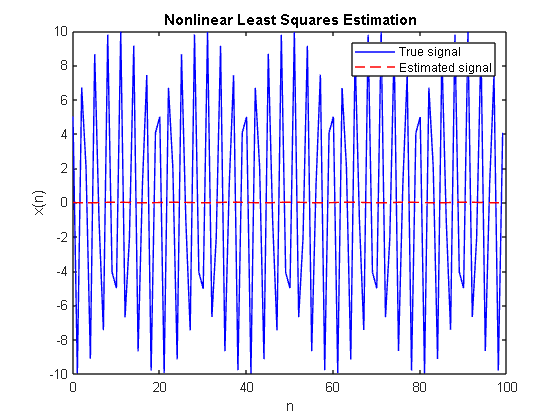


% Plot the true and estimated signals
figure;
plot(n, x, 'b', n, A_estimated*cos(2*pi*f0_estimated*n + phi_estimated), 'r--');
legend('True signal', 'Estimated signal');
xlabel('n');
ylabel('x(n)');
title('Nonlinear Least Squares Estimation');

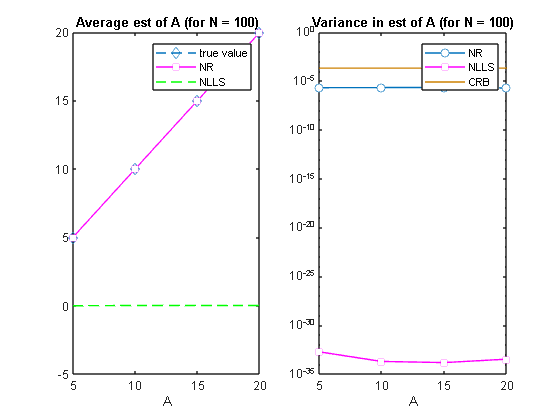

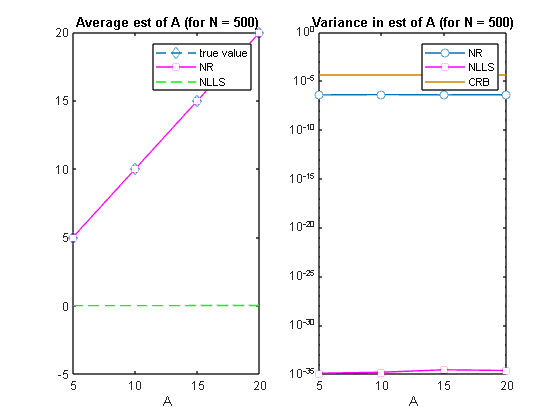

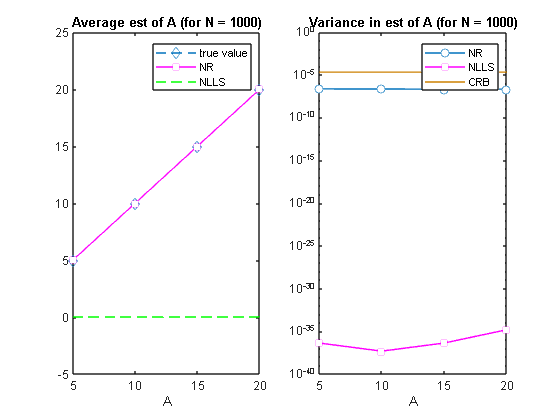

% Monte Carlo Simulations with varying A and N
MC=1000; 

N_vec = [100, 500, 1000]; % Array of N values
A_vec = [5, 10, 15, 20];

% Preallocate matrices to store results
av_phi_NR_est = zeros(length(N_vec), length(A_vec));
av_A_NLLS_est = zeros(length(N_vec), length(A_vec));
var_A_NR_est = zeros(length(N_vec), length(A_vec));
var_A_NLLS_est = zeros(length(N_vec), length(A_vec));
crb_A = zeros(length(N_vec), length(A_vec));

for nx = 1:length(A_vec)
    A_true = A_vec(nx);

    for sx = 1:length(N_vec)
        N = N_vec(sx);
        n = (0:N-1)';
        
        x = A_true*cos(2*pi*f0_true.*n+phi);

        est_A_NR_mat = zeros(MC, 1);
        est_A_NLLS_mat = zeros(MC, 1);

        for mx = 1:MC
            w = randn(N,1)*sig;
            y = x + w;
            A_init = 1;
            est_A_NR_mat(mx) = newton_raphson_A(n,sig,A_init,y,tol,f0_true,phi);

            A_guess = 9;
            f0_guess = 0.15;
            phi_guess = pi/4;
            initial_guess = [A_guess, f0_guess, phi_guess];
            % Define the objective function
            objective_function = @(params) params(1)*cos(2*pi*params(2)*n + params(3)) - x;
            % Perform nonlinear least squares estimation
            options = optimoptions('lsqnonlin', 'Display', 'off');
            estimated_params = lsqnonlin(objective_function, initial_guess, [], [], options);
            % Extract the estimated parameters
            A_estimated = estimated_params(1);

            est_A_NLLS_mat(mx) = A_estimated;       
        end

        % Compute CRB for this particular A_true and N
        crb_A(sx, nx) = (2*sig)/N;
        
        % Store the average and variance of estimates
        av_A_NR_est(sx, nx) = mean(est_A_NR_mat);
        av_A_NLLS_est(sx, nx) = mean(est_A_NLLS_mat);
        var_A_NR_est(sx, nx) = var(est_A_NR_mat);
        var_A_NLLS_est(sx, nx) = var(est_A_NLLS_mat);
    end
end

% Plot bias and variance
bias_A_NR = (av_A_NR_est - A_vec).^2;
bias_A_NLLS = (av_A_NLLS_est - A_vec).^2;

% Plot bias and variance for each N value
for sx = 1:length(N_vec)
    figure;
    subplot(1, 2, 1);
    plot(A_vec, A_vec,'d--');
    hold on;
    plot(A_vec, av_A_NR_est(sx, :), 's-', 'Color', 'm', 'MarkerFaceColor', 'w');
    plot(A_vec, av_A_NLLS_est(sx, :), '--', 'Color', 'g');
    hold off;
    xlabel('A')
    title(['Average est of A (for N = ', num2str(N_vec(sx)), ')'])
    legend('true value', 'NR', 'NLLS')

    subplot(1, 2, 2);
    semilogy(A_vec, var_A_NR_est(sx, :), 'o-', 'MarkerFaceColor', 'w');
    hold on;
    semilogy(A_vec, var_A_NLLS_est(sx, :), 's-', 'Color', 'm', 'MarkerFaceColor', 'w');
    semilogy(A_vec, crb_A(sx, :), 'Color', [0.8, 0.5, 0]);
    hold off;
    %ylim([0.8*min(crb_A(sx, :)), 2*max(crb_A(sx, :))]);
    xlabel('A')
    title(['Variance in est of A (for N = ', num2str(N_vec(sx)), ')'])
    legend('NR', 'NLLS', 'CRB');
end

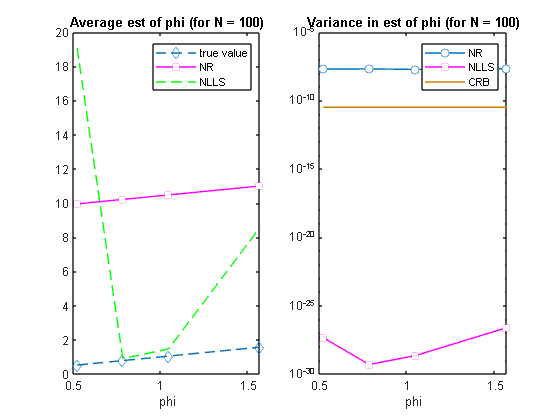

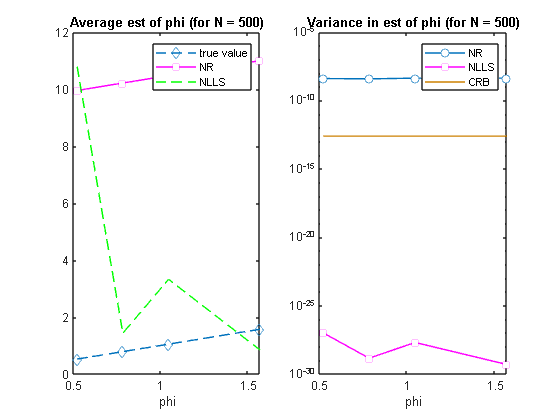

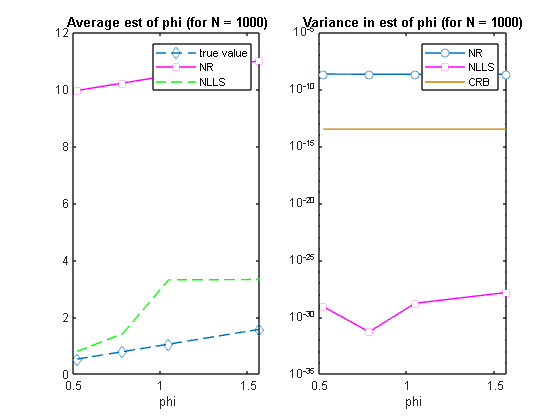

% Monte Carlo Simulations with varying phi and N
MC=1000; 

N_vec = [100, 500, 1000]; % Array of N values
phi_vec = [pi/6, pi/4, pi/3, pi/2];

% Preallocate matrices to store results
av_phi_NR_est = zeros(length(N_vec), length(phi_vec));
av_phi_NLLS_est = zeros(length(N_vec), length(phi_vec));
var_phi_NR_est = zeros(length(N_vec), length(phi_vec));
var_phi_NLLS_est = zeros(length(N_vec), length(phi_vec));
crb_phi = zeros(length(N_vec), length(phi_vec));

for nx = 1:length(phi_vec)
    phi_true = phi_vec(nx);

    for sx = 1:length(N_vec)
        N = N_vec(sx);
        n = (0:N-1)';
        
        x = A_original*cos(2*pi*f0_true.*n+phi_true);

        est_phi_NR_mat = zeros(MC, 1);
        est_phi_NLLS_mat = zeros(MC, 1);

        for mx = 1:MC
            w = randn(N,1)*sig;
            y = x + w;
            est_phi_NR_mat(mx) = newton_raphson_phi(n,sig,A_original,y,tol,f0_true,phi_true);

            A_guess = 1;
            f0_guess = 0.15;
            phi_guess = pi/4;
            initial_guess = [A_guess, f0_guess, phi_guess];
            % Define the objective function
            objective_function = @(params) params(1)*cos(2*pi*params(2)*n + params(3)) - x;
            % Perform nonlinear least squares estimation
            options = optimoptions('lsqnonlin', 'Display', 'off');
            estimated_params = lsqnonlin(objective_function, initial_guess, [], [], options);
            % Extract the estimated parameters
            phi_estimated = estimated_params(3);

            est_phi_NLLS_mat(mx) = phi_estimated;       
        end

        % Compute CRB for this particular phi_true and N
        crb_phi(sx, nx) = (3*sig)/( (A_original^2)*N*(N-1)*(N-2)*(pi^2));
        
        % Store the average and variance of estimates
        av_phi_NR_est(sx, nx) = mean(est_phi_NR_mat);
        av_phi_NLLS_est(sx, nx) = mean(est_phi_NLLS_mat);
        var_phi_NR_est(sx, nx) = var(est_phi_NR_mat);
        var_phi_NLLS_est(sx, nx) = var(est_phi_NLLS_mat);
    end
end

% Plot bias and variance
bias_phi_NR = (av_phi_NR_est - phi_vec).^2;
bias_phi_NLLS = (av_phi_NLLS_est - phi_vec).^2;

% Plot bias and variance for each N value
for sx = 1:length(N_vec)
    figure;
    subplot(1, 2, 1);
    plot(phi_vec, phi_vec,'d--');
    hold on;
    plot(phi_vec, av_phi_NR_est(sx, :), 's-', 'Color', 'm', 'MarkerFaceColor', 'w');
    plot(phi_vec, av_phi_NLLS_est(sx, :), '--', 'Color', 'g');
    hold off;
    xlabel('phi')
    title(['Average est of phi (for N = ', num2str(N_vec(sx)), ')'])
    legend('true value', 'NR', 'NLLS')

    subplot(1, 2, 2);
    semilogy(phi_vec, var_phi_NR_est(sx, :), 'o-', 'MarkerFaceColor', 'w');
    hold on;
    semilogy(phi_vec, var_phi_NLLS_est(sx, :), 's-', 'Color', 'm', 'MarkerFaceColor', 'w');
    semilogy(phi_vec, crb_phi(sx, :), 'Color', [0.8, 0.5, 0]);
    hold off;
    %ylim([0.8*min(crb_A(sx, :)), 2*max(crb_A(sx, :))]);
    xlabel('phi')
    title(['Variance in est of phi (for N = ', num2str(N_vec(sx)), ')'])
    legend('NR', 'NLLS', 'CRB');
end

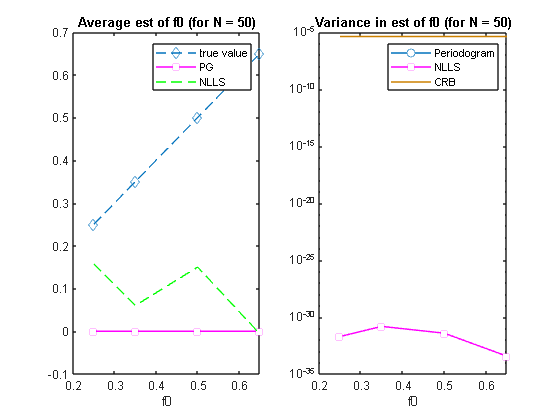

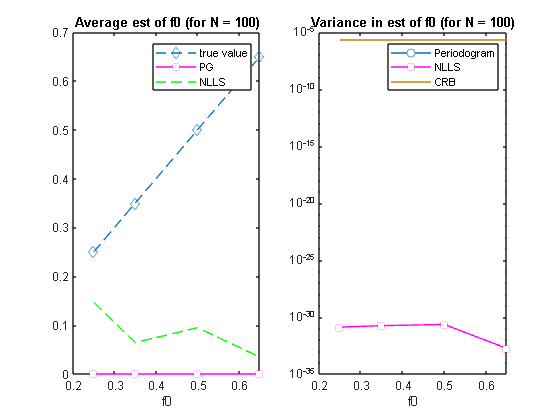

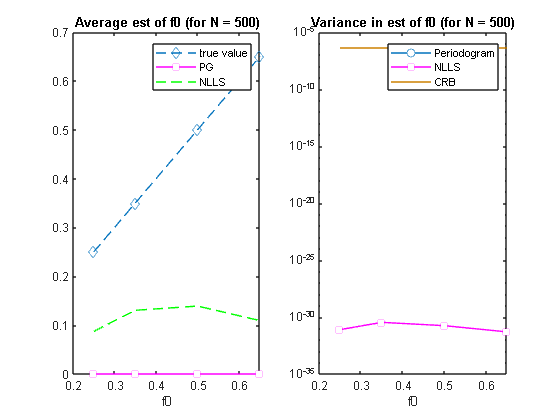

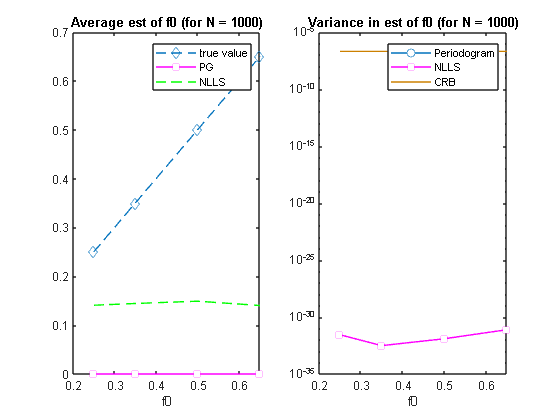

% Monte Carlo Simulations with varying f0 and N
MC=1000; 

N_vec = [50, 100, 500, 1000]; % Array of N values
f0_vec = [0.25, 0.35, 0.50, 0.65];

% Preallocate matrices to store results
av_f0_PG_est = zeros(length(N_vec), length(f0_vec));
av_f0_NLLS_est = zeros(length(N_vec), length(f0_vec));
var_f0_PG_est = zeros(length(N_vec), length(f0_vec));
var_f0_NLLS_est = zeros(length(N_vec), length(f0_vec));
crb_f0 = zeros(length(N_vec), length(f0_vec));

for nx = 1:length(f0_vec)
    f0_val = f0_vec(nx);

    for sx = 1:length(N_vec)
        N = N_vec(sx);
        n = (0:N-1)';
        
        x = A_original*cos(2*pi*f0_val.*n+phi);

        est_f0_PG_mat = zeros(MC, 1);
        est_f0_NLLS_mat = zeros(MC, 1);

        for mx = 1:MC
            w = randn(N,1)*sig;
            y = x + w;
            est_f0_PG_mat(mx) = Estimate_f0(f0_val,n,N);

            A_guess = 1;
            f0_guess = 0.15;
            phi_guess = pi/4;
            initial_guess = [A_guess, f0_guess, phi_guess];
            % Define the objective function
            objective_function = @(params) params(1)*cos(2*pi*params(2)*n + params(3)) - x;
            % Perform nonlinear least squares estimation
            options = optimoptions('lsqnonlin', 'Display', 'off');
            estimated_params = lsqnonlin(objective_function, initial_guess, [], [], options);
            % Extract the estimated parameters
            f0_estimated = estimated_params(2);

            est_f0_NLLS_mat(mx) = f0_estimated;       
        end

        % Compute CRB for this particular phi_true and N
        crb_f0(sx, nx) = 2*sig/(N*(A_original^2));
        
        % Store the average and variance of estimates
        av_f0_PG_est(sx, nx) = mean(est_f0_PG_mat);
        av_f0_NLLS_est(sx, nx) = mean(est_f0_NLLS_mat);
        var_f0_PG_est(sx, nx) = var(est_f0_PG_mat);
        var_f0_NLLS_est(sx, nx) = var(est_f0_NLLS_mat);
    end
end

% Plot bias and variance
bias_f0_PG = (av_f0_PG_est - f0_vec).^2;
bias_f0_NLLS = (av_f0_NLLS_est - f0_vec).^2;

% Plot bias and variance for each N value
for sx = 1:length(N_vec)
    figure;
    subplot(1, 2, 1);
    plot(f0_vec, f0_vec,'d--');
    hold on;
    plot(f0_vec, av_f0_PG_est(sx, :), 's-', 'Color', 'm', 'MarkerFaceColor', 'w');
    plot(f0_vec, av_f0_NLLS_est(sx, :), '--', 'Color', 'g');
    hold off;
    xlabel('f0')
    title(['Average est of f0 (for N = ', num2str(N_vec(sx)), ')'])
    legend('true value', 'PG', 'NLLS')

    subplot(1, 2, 2);
    semilogy(f0_vec, var_f0_PG_est(sx, :), 'o-', 'MarkerFaceColor', 'w');
    hold on;
    semilogy(f0_vec, var_f0_NLLS_est(sx, :), 's-', 'Color', 'm', 'MarkerFaceColor', 'w');
    semilogy(f0_vec, crb_f0(sx, :), 'Color', [0.8, 0.5, 0]);
    hold off;
    %ylim([0.8*min(crb_A(sx, :)), 2*max(crb_A(sx, :))]);
    xlabel('f0')
    title(['Variance in est of f0 (for N = ', num2str(N_vec(sx)), ')'])
    legend('Periodogram', 'NLLS', 'CRB');
end

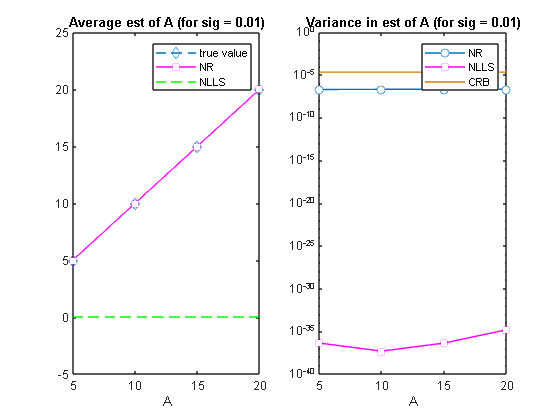

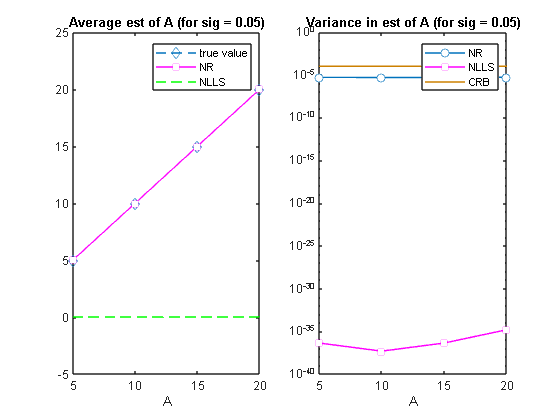

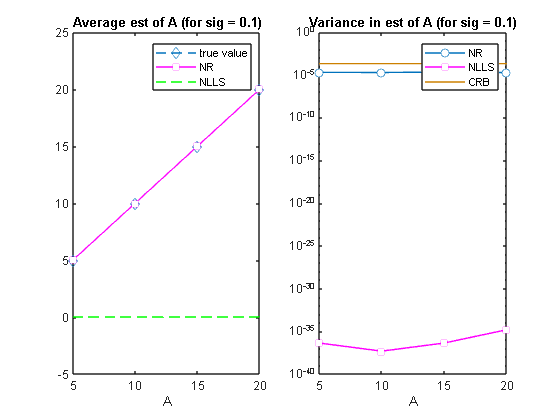

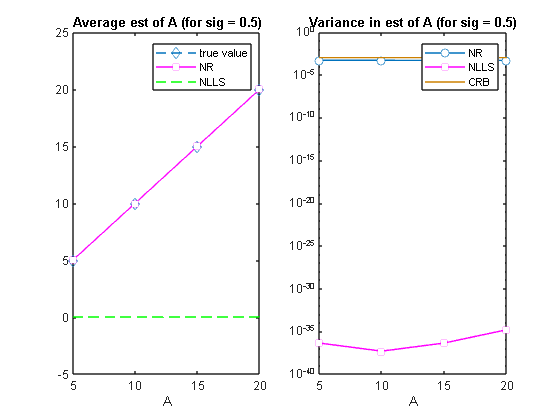

% Monte Carlo Simulations with varing A and sig
MC = 1000;

sig_vec = [0.01, 0.05, 0.1, 0.5]; % Array of sig values
A_vec = [5, 10, 15, 20];

% Preallocate matrices to store results
av_A_NR_est = zeros(length(sig_vec), length(A_vec));
av_A_NLLS_est = zeros(length(sig_vec), length(A_vec));
var_A_NR_est = zeros(length(sig_vec), length(A_vec));
var_A_NLLS_est = zeros(length(sig_vec), length(A_vec));
crb_A = zeros(length(sig_vec), length(A_vec));

for sx = 1:length(sig_vec)
    sig = sig_vec(sx);

    for nx = 1:length(A_vec)
        A_true = A_vec(nx);

        n = (0:N-1)';

        x = A_true * cos(2 * pi * f0_true .* n + phi);

        est_A_NR_mat = zeros(MC, 1);
        est_A_NLLS_mat = zeros(MC, 1);

        for mx = 1:MC
            w = randn(N,1) * sig;
            y = x + w;
            A_init = 1;
            est_A_NR_mat(mx) = newton_raphson_A(n, sig, A_init, y, tol, f0_true, phi);

            A_guess = 9;
            f0_guess = 0.15;
            phi_guess = pi/4;
            initial_guess = [A_guess, f0_guess, phi_guess];
            % Define the objective function
            objective_function = @(params) params(1) * cos(2 * pi * params(2) * n + params(3)) - x;
            % Perform nonlinear least squares estimation
            options = optimoptions('lsqnonlin', 'Display', 'off');
            estimated_params = lsqnonlin(objective_function, initial_guess, [], [], options);
            % Extract the estimated parameters
            A_estimated = estimated_params(1);

            est_A_NLLS_mat(mx) = A_estimated;
        end

        % Compute CRB for this particular A_true and N
        crb_A(sx, nx) = (2 * sig) / N;

        % Store the average and variance of estimates
        av_A_NR_est(sx, nx) = mean(est_A_NR_mat);
        av_A_NLLS_est(sx, nx) = mean(est_A_NLLS_mat);
        var_A_NR_est(sx, nx) = var(est_A_NR_mat);
        var_A_NLLS_est(sx, nx) = var(est_A_NLLS_mat);
    end
end

%Find bias and variance
bias_A_NR = (av_A_NR_est - A_vec).^2;
bias_A_NLLS = (av_A_NLLS_est - A_vec).^2;

% Plot bias and variance for each sig value
for sx = 1:length(sig_vec)
    figure;
    subplot(1, 2, 1);
    plot(A_vec, A_vec, 'd--');
    hold on;
    plot(A_vec, av_A_NR_est(sx, :), 's-', 'Color', 'm', 'MarkerFaceColor', 'w');
    plot(A_vec, av_A_NLLS_est(sx, :), '--', 'Color', 'g');
    hold off;
    xlabel('A')
    title(['Average est of A (for sig = ', num2str(sig_vec(sx)), ')'])
    legend('true value', 'NR', 'NLLS')

    subplot(1, 2, 2);
    semilogy(A_vec, var_A_NR_est(sx, :), 'o-', 'MarkerFaceColor', 'w');
    hold on;
    semilogy(A_vec, var_A_NLLS_est(sx, :), 's-', 'Color', 'm', 'MarkerFaceColor', 'w');
    semilogy(A_vec, crb_A(sx, :), 'Color', [0.8, 0.5, 0]);
    hold off;
    %ylim([0.8*min(crb_A(sx, :)), 2*max(crb_A(sx, :))]);
    xlabel('A')
    title(['Variance in est of A (for sig = ', num2str(sig_vec(sx)), ')'])
    legend('NR', 'NLLS', 'CRB');
end

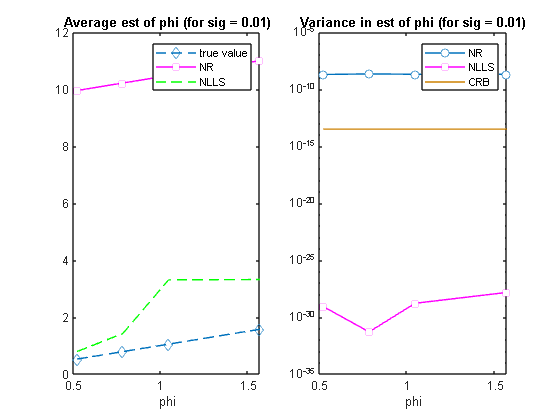

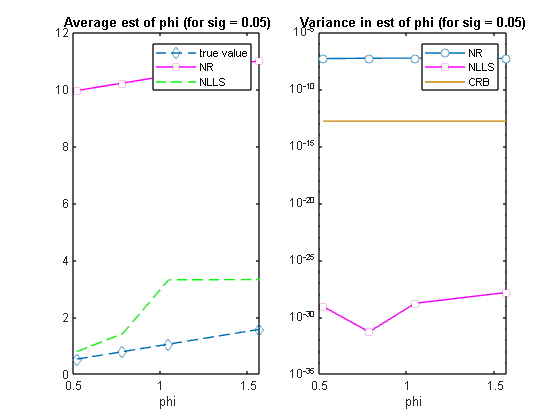

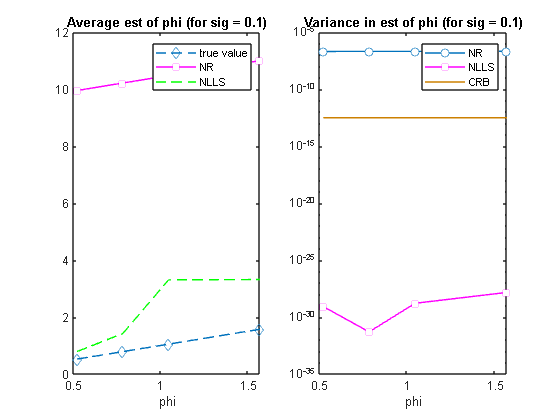

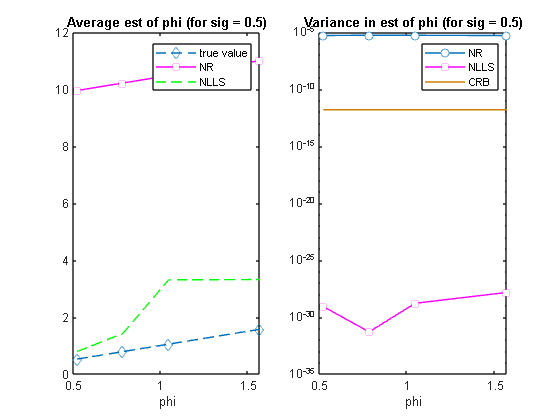

% Monte Carlo Simulations with varying phi and sig
MC = 1000;
sig_vec = [0.01, 0.05, 0.1, 0.5]; % Array of sig values
phi_vec = [pi/6, pi/4, pi/3, pi/2]; % Array of true phase angles

% Preallocate matrices to store results
av_phi_NR_est = zeros(length(sig_vec), length(phi_vec));
av_phi_NLLS_est = zeros(length(sig_vec), length(phi_vec));
var_phi_NR_est = zeros(length(sig_vec), length(phi_vec));
var_phi_NLLS_est = zeros(length(sig_vec), length(phi_vec));
crb_phi = zeros(length(sig_vec), length(phi_vec));

for sx = 1:length(sig_vec)
    sig = sig_vec(sx);

    for nx = 1:length(phi_vec)
        phi_true = phi_vec(nx);

        n = (0:N-1)';
        
        x = A_original * cos(2*pi*f0_true .* n + phi_true);

        est_phi_NR_mat = zeros(MC, 1);
        est_phi_NLLS_mat = zeros(MC, 1);

        for mx = 1:MC
            w = randn(N,1) * sig;
            y = x + w;
            est_phi_NR_mat(mx) = newton_raphson_phi(n, sig, A_original, y, tol, f0_true, phi_true);

            A_guess = 1;
            f0_guess = 0.15;
            phi_guess = pi/4;
            initial_guess = [A_guess, f0_guess, phi_guess];
            % Define the objective function
            objective_function = @(params) params(1) * cos(2*pi*params(2)*n + params(3)) - x;
            % Perform nonlinear least squares estimation
            options = optimoptions('lsqnonlin', 'Display', 'off');
            estimated_params = lsqnonlin(objective_function, initial_guess, [], [], options);
            % Extract the estimated parameters
            phi_estimated = estimated_params(3);

            est_phi_NLLS_mat(mx) = phi_estimated;       
        end

        % Compute CRB for this particular phi_true and N
        crb_phi(sx, nx) = (3 * sig) / ((A_original^2) * N * (N-1) * (N-2) * (pi^2));
        
        % Store the average and variance of estimates
        av_phi_NR_est(sx, nx) = mean(est_phi_NR_mat);
        av_phi_NLLS_est(sx, nx) = mean(est_phi_NLLS_mat);
        var_phi_NR_est(sx, nx) = var(est_phi_NR_mat);
        var_phi_NLLS_est(sx, nx) = var(est_phi_NLLS_mat);
    end
end

% Plot bias and variance
bias_phi_NR = (av_phi_NR_est - phi_vec).^2;
bias_phi_NLLS = (av_phi_NLLS_est - phi_vec).^2;

% Plot bias and variance for each sig value
for sx = 1:length(sig_vec)
    figure;
    subplot(1, 2, 1);
    plot(phi_vec, phi_vec, 'd--');
    hold on;
    plot(phi_vec, av_phi_NR_est(sx, :), 's-', 'Color', 'm', 'MarkerFaceColor', 'w');
    plot(phi_vec, av_phi_NLLS_est(sx, :), '--', 'Color', 'g');
    hold off;
    xlabel('phi')
    title(['Average est of phi (for sig = ', num2str(sig_vec(sx)), ')'])
    legend('true value', 'NR', 'NLLS')

    subplot(1, 2, 2);
    semilogy(phi_vec, var_phi_NR_est(sx, :), 'o-', 'MarkerFaceColor', 'w');
    hold on;
    semilogy(phi_vec, var_phi_NLLS_est(sx, :), 's-', 'Color', 'm', 'MarkerFaceColor', 'w');
    semilogy(phi_vec, crb_phi(sx, :), 'Color', [0.8, 0.5, 0]);
    hold off;
    xlabel('phi')
    title(['Variance in est of phi (for sig = ', num2str(sig_vec(sx)), ')'])
    legend('NR', 'NLLS', 'CRB');
end

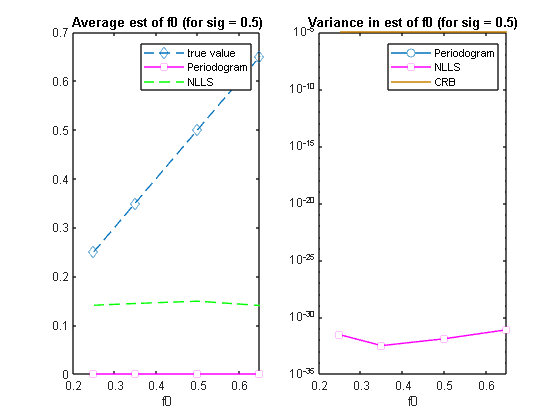

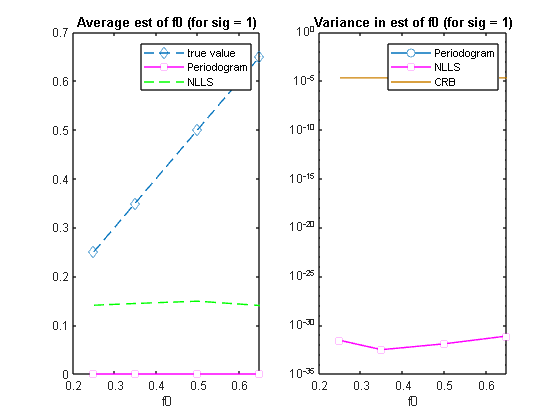

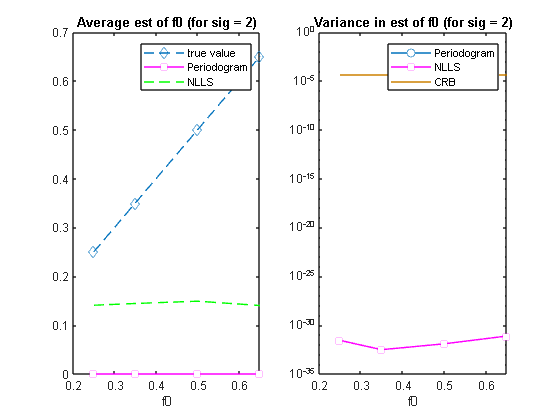

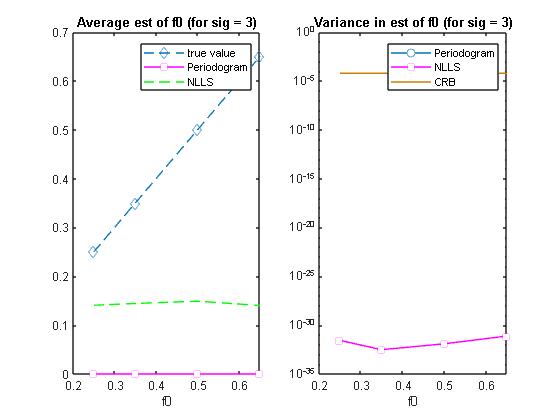

% Monte Carlo Simulations with varying f0 and sig
MC=1000; 
sig_vec = [0.5, 1, 2, 3]; % Array of sig values
f0_vec = [0.25, 0.35, 0.50, 0.65]; % Array of true frequencies

% Preallocate matrices to store results
av_f0_PG_est = zeros(length(sig_vec), length(f0_vec));
av_f0_NLLS_est = zeros(length(sig_vec), length(f0_vec));
var_f0_PG_est = zeros(length(sig_vec), length(f0_vec));
var_f0_NLLS_est = zeros(length(sig_vec), length(f0_vec));
crb_f0 = zeros(length(sig_vec), length(f0_vec));

for sx = 1:length(sig_vec)
    sig = sig_vec(sx);

    for nx = 1:length(f0_vec)
        f0_val = f0_vec(nx);

        n = (0:N-1)';
        
        x = A_original * cos(2*pi*f0_val .* n + phi);

        est_f0_PG_mat = zeros(MC, 1);
        est_f0_NLLS_mat = zeros(MC, 1);

        for mx = 1:MC
            w = randn(N,1) * sig;
            y = x + w;
            est_f0_PG_mat(mx) = Estimate_f0(f0_val, n, N);

            A_guess = 1;
            f0_guess = 0.15;
            phi_guess = pi/4;
            initial_guess = [A_guess, f0_guess, phi_guess];
            % Define the objective function
            objective_function = @(params) params(1) * cos(2*pi*params(2)*n + params(3)) - x;
            % Perform nonlinear least squares estimation
            options = optimoptions('lsqnonlin', 'Display', 'off');
            estimated_params = lsqnonlin(objective_function, initial_guess, [], [], options);
            % Extract the estimated parameters
            f0_estimated = estimated_params(2);

            est_f0_NLLS_mat(mx) = f0_estimated;       
        end

        % Compute CRB for this particular f0_val and N
        crb_f0(sx, nx) = 2 * sig / (N * (A_original^2));
        
        % Store the average and variance of estimates
        av_f0_PG_est(sx, nx) = mean(est_f0_PG_mat);
        av_f0_NLLS_est(sx, nx) = mean(est_f0_NLLS_mat);
        var_f0_PG_est(sx, nx) = var(est_f0_PG_mat);
        var_f0_NLLS_est(sx, nx) = var(est_f0_NLLS_mat);
    end
end

% Plot bias and variance
bias_f0_PG = (av_f0_PG_est - f0_vec).^2;
bias_f0_NLLS = (av_f0_NLLS_est - f0_vec).^2;

% Plot bias and variance for each sig value
for sx = 1:length(sig_vec)
    figure;
    subplot(1, 2, 1);
    plot(f0_vec, f0_vec, 'd--');
    hold on;
    plot(f0_vec, av_f0_PG_est(sx, :), 's-', 'Color', 'm', 'MarkerFaceColor', 'w');
    plot(f0_vec, av_f0_NLLS_est(sx, :), '--', 'Color', 'g');
    hold off;
    xlabel('f0')
    title(['Average est of f0 (for sig = ', num2str(sig_vec(sx)), ')'])
    legend('true value', 'Periodogram', 'NLLS')

    subplot(1, 2, 2);
    semilogy(f0_vec, var_f0_PG_est(sx, :), 'o-', 'MarkerFaceColor', 'w');
    hold on;
    semilogy(f0_vec, var_f0_NLLS_est(sx, :), 's-', 'Color', 'm', 'MarkerFaceColor', 'w');
    semilogy(f0_vec, crb_f0(sx, :), 'Color', [0.8, 0.5, 0]);
    hold off;
    xlabel('f0')
    title(['Variance in est of f0 (for sig = ', num2str(sig_vec(sx)), ')'])
    legend('Periodogram', 'NLLS', 'CRB');
end

function f_est=Estimate_f0(x,n,N)
    f_range = linspace(0, 0.5, 1000);
    
    % Find the frequency f for which fun is maximized
    s = sum(x .* exp(-1i * 2 * pi * f_range .* n));
    fun = abs(s).^2 / N;
    [~, idx] = max(fun); %maximizing this function gives estimate of f
    f_est = f_range(idx);
end

function A_est= newton_raphson_A(n,sig,A_init,x,tol,f0,phi)
    A_est = A_init;
    max_iter = 1000;
    iter = 1;
    while iter <= max_iter
        % Compute the gradient and Hessian of the log-likelihood function
        grad = sum((x - A_est*cos(2*pi*f0.*n+phi)).*cos(2*pi*f0.*n+phi))/sig;
        hess = -sum(cos(2*pi*f0.*n+phi).^2)/sig;
        
        % Update A using Newton-Raphson method
        A_est_old = A_est;
        A_est = A_est - grad/hess;
        
        % Check for convergence
        if abs(A_est - A_est_old) < tol
            break;
        end
        
        iter = iter + 1;
    end
end


function phi_est=newton_raphson_phi(n,sig,phi_init,x,tol,f0,A_original)
    phi_est = phi_init;
    max_iter = 1000;
    iter = 1;
    while iter <= max_iter
        % Compute the gradient and Hessian of the log-likelihood function
        grad = -sum((x - A_original*cos(2*pi*f0.*n+phi_est)).*A_original.*sin(2*pi*f0.*n+phi_est))/sig;
        hess = -A_original*sum((x - A_original*cos(2*pi*f0.*n+phi_est)).*cos(2*pi*f0.*n+phi_est)+A_original.*sin(2*pi*f0.*n+phi_est).^2)/sig;
        
        % Update ∅  using Newton-Raphson method
        phi_est_old = phi_est;
        phi_est = phi_est - grad/hess;
        
        % Check for convergence
        if abs(phi_est - phi_est_old) < tol
            break;
        end
        
        iter = iter + 1;
    end
end